# Control predictivo del péndulo invertido sobre carro: MPC y Gain Scheduling

Control Multivariable · Pontificia Universidad Javeriana · Segundo parcial · Noviembre de 2026

## 1. Planteamiento físico

Se parte de la misma planta del proyecto, obtenida a partir del balance de fuerzas y momentos. El objetivo es mantener θ = 0 (vertical superior) y controlar la posición x del carro. F es la fuerza manipulada y dF es una perturbación horizontal aplicada sobre el péndulo.

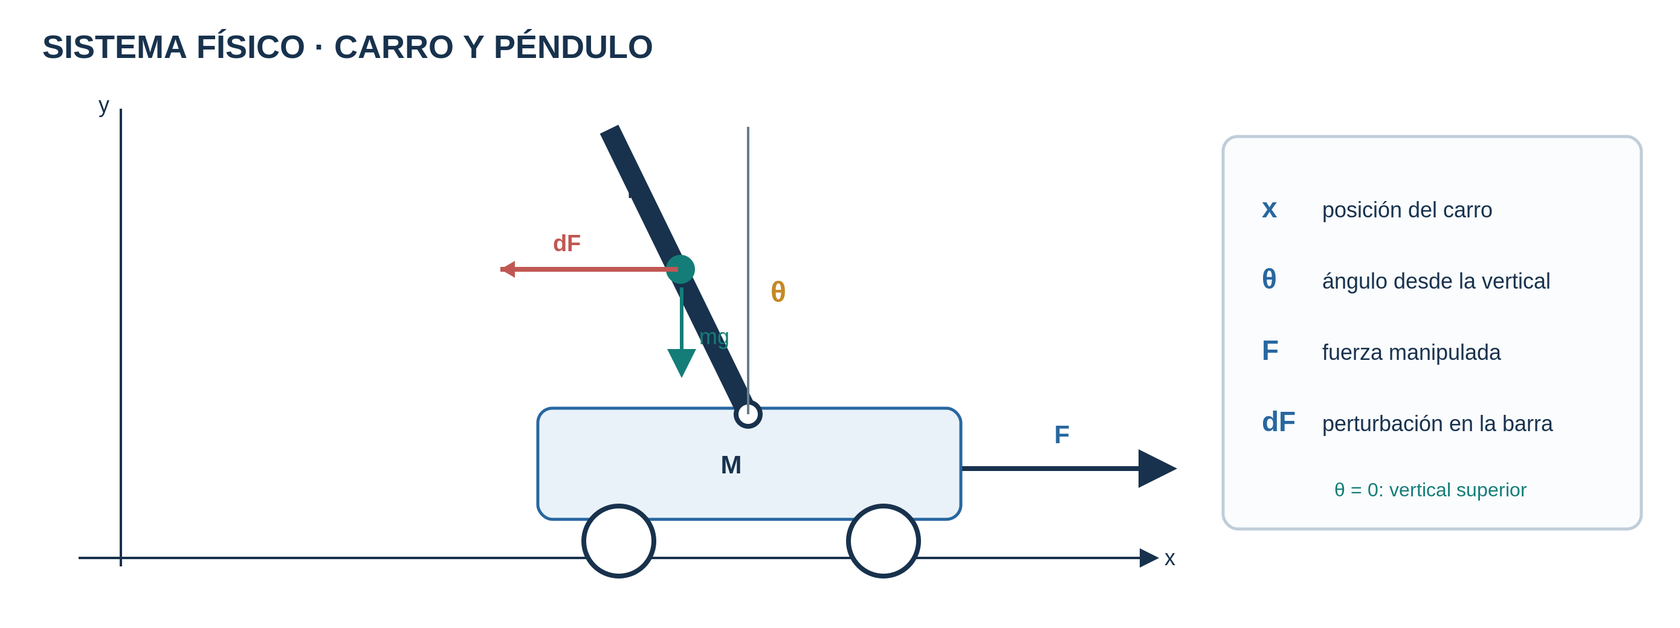

Figura 1. Modelo físico y convención de signos empleada en la derivación. Esquema propio basado en las referencias del segundo parcial.

Fuente de la formulación y figura de referencia: https://www.mathworks.com/help/symbolic/derive-and-simulate-cart-pole-system.html

## 2. Parámetros, estados y entradas

Los parámetros utilizados provienen de los bloques del proyecto: M = 0.380 kg, m = 0.230 kg, l = 0.3302 m, I = 0.00788 kg·m², b = 0.0024 N·s/m y g = 9.81 m/s². Se conservan estos valores en las cuatro estrategias.


$$z=\left[\matrix{\theta\cr\dot\theta\cr x\cr\dot x}\right],\qquad u=\left[\matrix{dF\cr F}\right]$$


El estado real del bloque YdotBlock se ordena como [θ; θ̇; x; ẋ]. Las columnas de B0 son [dF, F]. Para los Scopes se presenta [θ, θ̇, x, ẋ]; la planta lineal usa las dos entradas físicas en el mismo orden que la no lineal. Se documenta la permutación de columnas necesaria en el generador.

M = 0.380;
m = 0.230;
l = 0.3302;
I = 7.88e-3;
b = 0.0024;
g = 9.81;
CART_P = [M; m; l; I; b; g];

X_INIT = [deg2rad(3); 0; 0; 0];
SIM_MODE = 3;
SIM_TSTOP = 8;
REF_X = 0.10;
OPEN_FORCE = 0.05;
DIST_FORCE = 0.05;
DIST_START = 4;
DIST_WIDTH = 0.10;


%% Simscape Multibody Parameters

L = 2*l;

mCart = M;
mPend = m;

Kd = b;
theta0 = rad2deg(X_INIT(1));

Gravity = g;


## 3. Modelo matemático no lineal

La eliminación de las fuerzas internas H y V, realizada en el Live Script original mediante Symbolic Math Toolbox, permite escribir dos ecuaciones acopladas en las aceleraciones del carro y del péndulo. Esta forma compacta facilita su implementación en el bloque MATLAB Function.


$$\left[\matrix{M+m & -ml\cos\theta\cr-ml\cos\theta & I+ml^2}\right]\left[\matrix{\ddot x\cr\ddot\theta}\right]=\left[\matrix{F-dF-b\dot x-ml\sin\theta\dot\theta^2\cr dFl\cos\theta+mgl\sin\theta}\right]$$


La primera fila corresponde a la traslación del carro; la segunda representa el giro de la barra. Al resolver este sistema 2 × 2 se obtienen ẍ y θ̈. Las mismas expresiones alimentan la planta no lineal en Simulink.


$$\dot z=f(z,u)=\left[\matrix{\dot\theta\cr\ddot\theta\cr\dot x\cr\ddot x}\right]$$


syms theta omega xpos vel dF F real
z_sym = [theta; omega; xpos; vel];
u_sym = [dF; F];
H_sym = [M+m, -m*l*cos(theta); -m*l*cos(theta), I+m*l^2];
r_sym = [F-dF-b*vel-m*l*sin(theta)*omega^2; dF*l*cos(theta)+m*g*l*sin(theta)];
accelerations = simplify(H_sym \ r_sym);
f_sym = simplify([omega; accelerations(2); vel; accelerations(1)]);

assert(double(subs(det(H_sym),theta,0)) > 0, 'Mass matrix must be nonsingular at upright.');
disp('Nonlinear state derivative f(z,[dF;F]) = ');

Nonlinear state derivative f(z,[dF;F]) = 


disp(f_sym);

$$\begin{array}{l} \left(\begin{array}{c} \omega \\ -\frac{-467939115984686714129209062900390625\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,\omega^{2}+36870861717061654583848382161223680000\,\sin\left(\theta \right)+6161471519035719017155683942400000000\,F\,\cos\left(\theta \right)+10179822509711188023373529051727659008\,\mathrm{dF}\,\cos\left(\theta \right)-14787531645685725641173641461760000\,\mathrm{vel}\,\cos\left(\theta \right)}{3125\,\sigma_{1}}\\ \mathrm{vel}\\ -\frac{2\,\left(-812263566672580150456708837640625\,\sin\left(\theta \right)\,\omega^{2}+8138071582342377677859227351121920\,\mathrm{dF}\,{\cos\left(\theta \right)}^{2}+18361930911239110852302285556637500\,\sin\left(\theta \right)\,\cos\left(\theta \right)+10695277785170781272639967068160000\,F-10695277785170781272639967068160000\,\mathrm{dF}-25668666684409875054335920963584\,\mathrm{vel}\right)}{25\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=149740517115099748521346900128125\,{\cos\left(\theta \right)}^{2}-521929555916334126104830392926208 \end{array}$$

## 4. Linealización en la posición vertical

El equilibrio superior está dado por z0 = [0;0;0;0] y u0 = [0;0]. Se obtienen los Jacobianos A0 = ∂f/∂z y B0 = ∂f/∂u evaluados en ese punto. A continuación se muestran sus valores numéricos para verificar que la planta del proyecto y el modelo predictivo comparten parámetros y orden de variables.


$$A_0=\left[\matrix{0&1&0&0\cr31.7008&0&0&-0.012714\cr0&0&0&1\cr3.9468&0&0&-0.005517}\right]$$



$$B_0=\left[\matrix{0&0\cr8.75239&5.29750\cr0&0\cr-0.54966&2.29889}\right],\quad [dF,F]$$


Se conservan cuatro estados en el sistema lineal y solo se consideran dos salidas medidas para el MPC: posición del carro x y ángulo θ. Las velocidades quedan disponibles para simulación y análisis, pero no entran en el puerto mo del controlador.


$$y=\left[\matrix{x\cr\theta}\right]=Cz,\qquad C=\left[\matrix{0&0&1&0\cr1&0&0&0}\right]$$


A_sym = simplify(jacobian(f_sym,z_sym));
B_sym = simplify(jacobian(f_sym,u_sym));
nominal_angles = [-4*pi/9, 0, 4*pi/9];   % [-80, 0, +80] deg
X_op = zeros(4,3);
U_op = zeros(2,3);
DX_op = zeros(4,3);
A_models = zeros(4,4,3);
B_models = zeros(4,2,3);

for k = 1:3
    X_op(:,k) = [nominal_angles(k); 0; 0; 0];
    U_op(:,k) = [0; 0];  % [dF; F] for every local point
    substitution_values = [X_op(:,k); U_op(:,k)];
    vars = [z_sym;u_sym];
    A_models(:,:,k) = double(subs(A_sym,vars,substitution_values));
    B_models(:,:,k) = double(subs(B_sym,vars,substitution_values));
    DX_op(:,k) = double(subs(f_sym,vars,substitution_values));
end

A0 = A_models(:,:,2);
B0 = B_models(:,:,2);      % input order [dF; F]
C_MPC = [0 0 1 0; 1 0 0 0];  % measured outputs [x;theta]
D_MPC = zeros(2,2);

% The existing State-Space block evaluates B_LIN(:,[2 1]).
% Its INPUT_DF_F signal is ordered [dF; F].
A_LIN = A0;
B_LIN = B0(:,[2 1]);
C_LIN = eye(4);
D_LIN = zeros(4,2);

A_reference = [0 1 0 0; 31.7007609559 0 0 -0.012713996473; 0 0 0 1; 3.94679670748 0 0 -0.00551733963302];
B_reference = [0 0; 8.75238887636 5.29749853043; 0 0; -0.549657499010 2.29889151376];
assert(norm(A0-A_reference,'fro') < 1e-7,'A0 no coincide con los parametros del modelo original.');
assert(norm(B0-B_reference,'fro') < 1e-7,'B0 no coincide con los parametros del modelo original.');
assert(norm(B_LIN(:,[2 1])-B0,'fro') < 1e-12,'Las entradas del bloque State-Space estan permutadas.');

fprintf('Upright A0 =\n'); disp(A0);

Upright A0 =
         0    1.0000         0         0
   31.7008         0         0   -0.0127
         0         0         0    1.0000
    3.9468         0         0   -0.0055



fprintf('Upright B0 ([dF;F]) =\n'); disp(B0);

Upright B0 ([dF;F]) =
         0         0
    8.7524    5.2975
         0         0
   -0.5497    2.2989



fprintf('Upright poles =\n'); disp(eig(A0));

Upright poles =
         0
    5.6296
   -5.6311
   -0.0039



assert(any(real(eig(A0))>0),'The upright equilibrium should be unstable.');
assert(norm(DX_op(:,2))<1e-10,'Upright must be a genuine equilibrium.');


La linealización en θ = 0 posee los polos aproximados {0, +5.62955, −5.63113, −0.00393}. El polo positivo es propio del equilibrio vertical sin realimentación: a tiempos largos, la respuesta lineal crece aun con matrices correctas. La planta lineal del archivo parcial_2_simulaciones.slx recibe INPUT_DF_F = [dF; F] y evalúa B = B_LIN(:,[2 1]); como B_LIN = B0(:,[2 1]), el bloque termina usando B0 en el orden correcto. Se comprueban numéricamente A0, B0 y esta correspondencia sin modificar el MPC ni las condiciones de simulación. Para comprobar la validez de la aproximación se deben comparar intervalos cortos y ángulos pequeños, no forzar estabilidad cambiando los coeficientes.

## 5. Verificación de la aproximación local

La aproximación de primer orden reproduce la dinámica alrededor del punto elegido, pero se separa de la planta real a medida que crece el ángulo. Para evaluar esa diferencia se calculan errores entre f(z,u) y el modelo afín local en desviaciones angulares de 1°, 5° y 15°. Los resultados permiten justificar el uso de varios modelos.


$$\epsilon_i=\left\|f(z,u)-\dot z_i-A_i(z-z_i)-B_i(u-u_i)\right\|_2$$


sample_delta_deg = [1, 5, 15];
linearization_error = zeros(3,3);
for k = 1:3
    for j = 1:numel(sample_delta_deg)
        zp = X_op(:,k)+[deg2rad(sample_delta_deg(j));0;0;0];
        up = U_op(:,k);
        fp = double(subs(f_sym,[z_sym;u_sym],[zp;up]));
        fl = DX_op(:,k)+A_models(:,:,k)*(zp-X_op(:,k)) +B_models(:,:,k)*(up-U_op(:,k));
        linearization_error(k,j) = norm(fp-fl,2);
    end
end
disp(array2table(linearization_error,'VariableNames', {'Error_1deg','Error_5deg','Error_15deg'},'RowNames', {'Minus80deg','ZeroDeg','Plus80deg'}));

                  Error_1deg    Error_5deg    Error_15deg
                  __________    __________    ___________

    Minus80deg     0.0016322     0.041981       0.41201  
    ZeroDeg       9.8466e-05      0.01225       0.31816  
    Plus80deg      0.0016117     0.039418       0.34295  



## 6. Diseño del MPC convencional

El controlador utiliza un modelo lineal para predecir la evolución del sistema. En cada instante optimiza una secuencia de fuerzas, aplica únicamente la primera y repite el cálculo. La referencia es [x_ref; 0], mientras dF se considera una perturbación no medida de la planta.

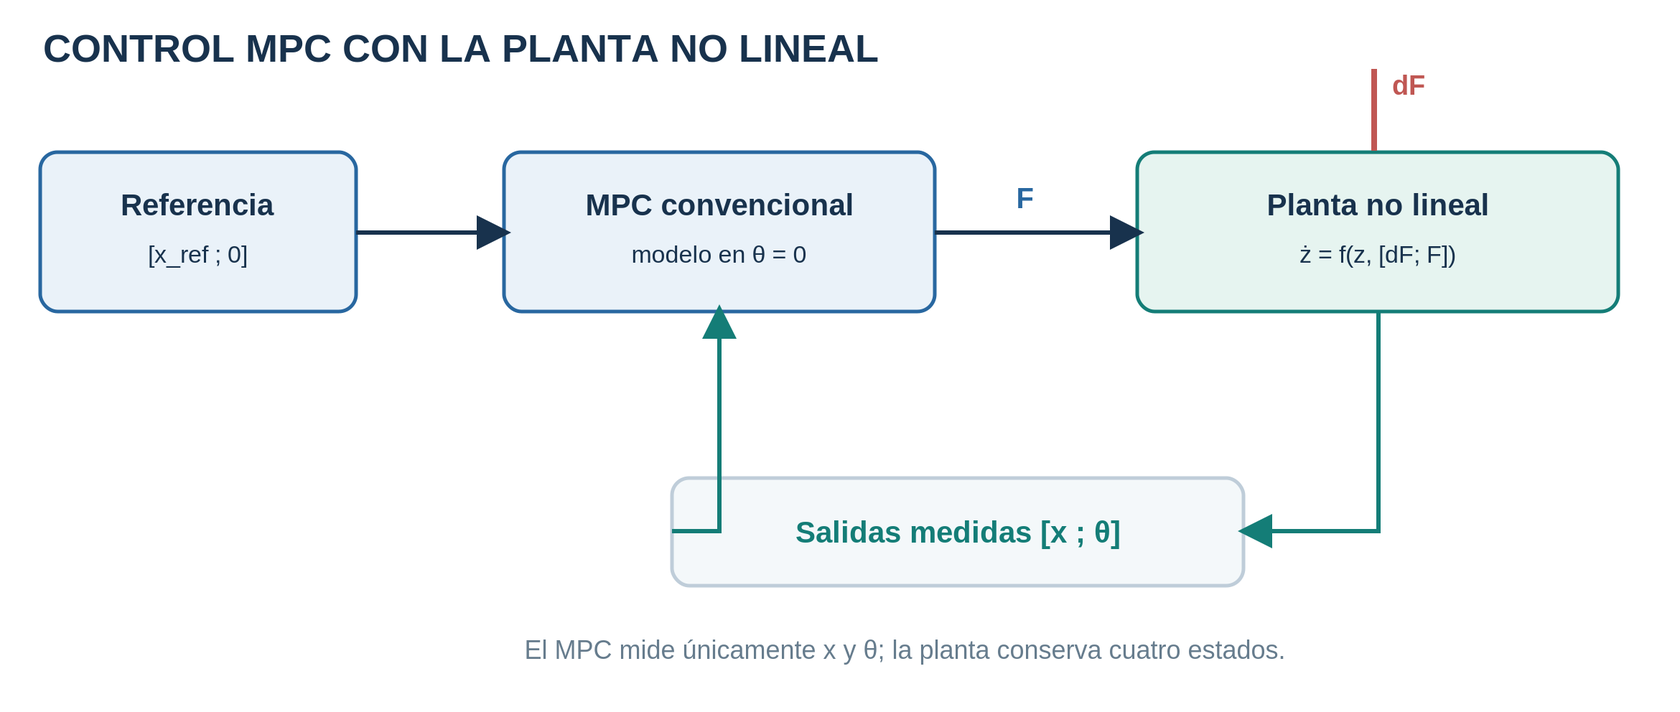

Figura 2. Estructura del MPC convencional: dos salidas medidas y una planta no lineal. Esquema propio basado en el ejemplo oficial de MathWorks.


$$\min_{\Delta U}\ J=\sum_{j=1}^{N_p}\|y_{k+j|k}-r_{k+j}\|_Q^2+\sum_{j=0}^{N_c-1}\|\Delta F_{k+j|k}\|_R^2$$



$$z_{k+1}=A_dz_k+B_du_k,\qquad -F_{\max}\leq F_k\leq F_{\max}$$


Se adopta inicialmente Ts = 0.01 s, horizonte de predicción de 50 pasos y horizonte de control de 5 pasos. El peso de seguimiento es [1.2, 1] para [x, θ]. El límite ±20 N se define como condición de ensayo, no como especificación de un actuador real.

TS_MPC = 0.01;       % Controller sample time [s]
N_PRED = 50;         % Prediction horizon [steps]
N_CTRL = 5;          % Control horizon [steps]
F_LIMIT = 20;        % Initial simulation force constraint [N]
F_SCALE = 10;        % MV scaling for numerical conditioning

plant_upright = ss(A0,B0,C_MPC,D_MPC);
plant_upright.StateName = {'theta','theta_dot','x','x_dot'};
plant_upright.InputName = {'dF','F'};
plant_upright.OutputName = {'x','theta'};
plant_upright = setmpcsignals(plant_upright,'ud',1,'mv',2);

mpc_nominal = mpc(plant_upright,TS_MPC,N_PRED,N_CTRL);

-->"Weights.ManipulatedVariables" is empty. Assuming default 0.00000.
-->"Weights.ManipulatedVariablesRate" is empty. Assuming default 0.10000.
-->"Weights.OutputVariables" is empty. Assuming default 1.00000.
   for output(s) y1 and zero weight for output(s) y2 


mpc_nominal.MV.Min = -F_LIMIT;
mpc_nominal.MV.Max = F_LIMIT;
mpc_nominal.MV.ScaleFactor = F_SCALE;
mpc_nominal.Weights.MVRate = 1;
mpc_nominal.Weights.OV = [1.2 1];
mpc_nominal.Model.Nominal.X = X_op(:,2);
mpc_nominal.Model.Nominal.U = U_op(:,2);
mpc_nominal.Model.Nominal.Y = C_MPC*X_op(:,2);
mpc_nominal.Model.Nominal.DX = DX_op(:,2);
assignin('base','mpc_nominal',mpc_nominal);


Referencia del esquema: https://www.mathworks.com/help/mpc/ug/mpc-control-of-an-inverted-pendulum-on-a-cart.html

## 7. Bono: Gain-Scheduled MPC

El bono utiliza tres linealizaciones locales en θ = −80°, 0° y +80°, siguiendo la metodología de MathWorks. Se construye un controlador MPC por región. En el modelo actual, tres MPC independientes reciben la misma referencia y las mismas mediciones; el selector de ángulo decide cuál fuerza se aplica a la única planta no lineal.

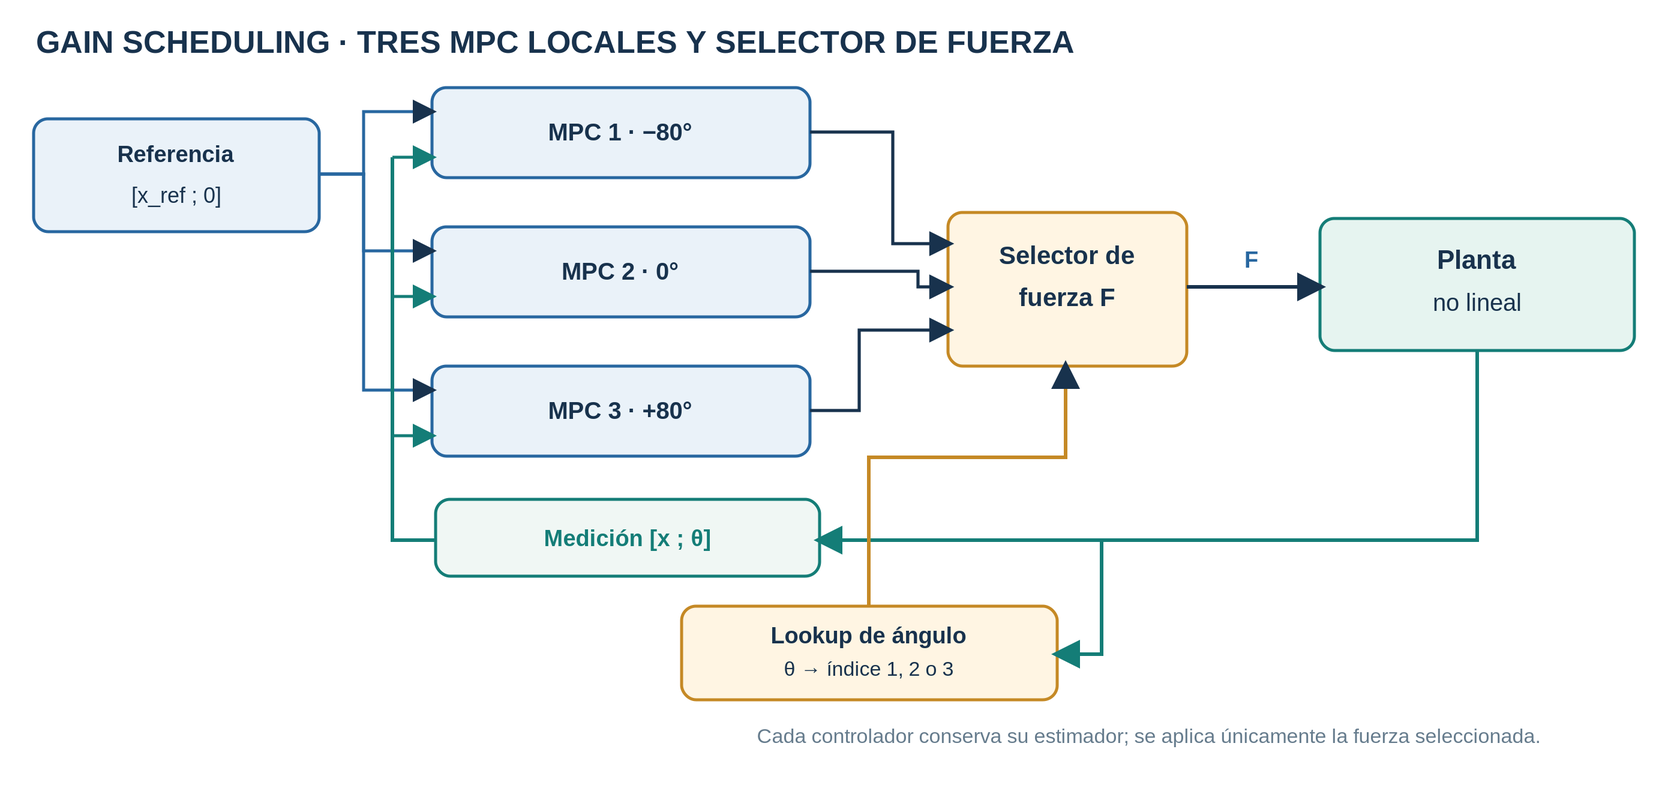

Figura 3. Implementación de Gain Scheduling con tres MPC locales y selección de fuerza. Esta topología es una adaptación del ejemplo de MathWorks y no el bloque Multiple MPC Controllers original.


$$\theta_i\in\left\{-\frac{4\pi}{9},\ 0,\ \frac{4\pi}{9}\right\},\qquad i=1,2,3$$



$$\dot z\approx\dot z_i+A_i(z-z_i)+B_i(u-u_i),\qquad\dot z_i=f(z_i,u_i)$$


Los puntos ±80° no son equilibrios estáticos: con velocidad y fuerzas nulas, el péndulo acelera por gravedad. Por ello se conserva Model.Nominal.DX para cada MPC, además de los estados y entradas nominales. Esto es indispensable para representar la expansión afín de la dinámica local.


$$j(\theta)=1\;\; (\theta<-40^{\circ}),\quad j(\theta)=2\;\; (|\theta|\leq40^{\circ}),\quad j(\theta)=3\;\; (\theta>40^{\circ})$$


GSControllers = cell(1,3);
GSPlants = cell(1,3);
for k = 1:3
    plant_i = ss(A_models(:,:,k),B_models(:,:,k),C_MPC,D_MPC);
    plant_i.StateName = {'theta','theta_dot','x','x_dot'};
    plant_i.InputName = {'dF','F'};
    plant_i.OutputName = {'x','theta'};
    plant_i = setmpcsignals(plant_i,'ud',1,'mv',2);

    controller_i = mpc(plant_i,TS_MPC,N_PRED,N_CTRL);
    controller_i.MV.Min = -F_LIMIT;
    controller_i.MV.Max = F_LIMIT;
    controller_i.MV.ScaleFactor = F_SCALE;
    controller_i.Weights.MVRate = 1;
    controller_i.Weights.OV = [1.2 1];
    controller_i.Model.Nominal.X = X_op(:,k);
    controller_i.Model.Nominal.U = U_op(:,k);
    controller_i.Model.Nominal.Y = C_MPC*X_op(:,k);
    controller_i.Model.Nominal.DX = DX_op(:,k);
    GSControllers{k} = controller_i;
    GSPlants{k} = plant_i;
end

-->"Weights.ManipulatedVariables" is empty. Assuming default 0.00000.
-->"Weights.ManipulatedVariablesRate" is empty. Assuming default 0.10000.
-->"Weights.OutputVariables" is empty. Assuming default 1.00000.
   for output(s) y1 and zero weight for output(s) y2 
-->"Weights.ManipulatedVariables" is empty. Assuming default 0.00000.
-->"Weights.ManipulatedVariablesRate" is empty. Assuming default 0.10000.
-->"Weights.OutputVariables" is empty. Assuming default 1.00000.
   for output(s) y1 and zero weight for output(s) y2 
-->"Weights.ManipulatedVariables" is empty. Assuming default 0.00000.
-->"Weights.ManipulatedVariablesRate" is empty. Assuming default 0.10000.
-->"Weights.OutputVariables" is empty. Assuming default 1.00000.
   for output(s) y1 and zero weight for output(s) y2 


mpc_gs_1 = GSControllers{1};
mpc_gs_2 = GSControllers{2};
mpc_gs_3 = GSControllers{3};
fprintf('Nonstationary nominal derivatives at +/-80 deg:\n');

Nonstationary nominal derivatives at +/-80 deg:


disp(DX_op(:,[1 3]));

         0         0
  -22.4567   22.4567
         0         0
   -0.4855    0.4855



La selección entre modelos puede mejorar las predicciones fuera de la vertical, pero no garantiza estabilidad global. Cada MPC independiente mantiene su propio estimador; por eso esta implementación no equivale exactamente a la gestión de estados del bloque Multiple MPC Controllers. La conmutación debe evaluarse en las pruebas.

Referencia del esquema: https://la.mathworks.com/help/mpc/ug/gain-scheduled-mpc-control-of-an-inverted-pendulum-on-a-cart.html

## 8. Integración en un único Simulink y comparación

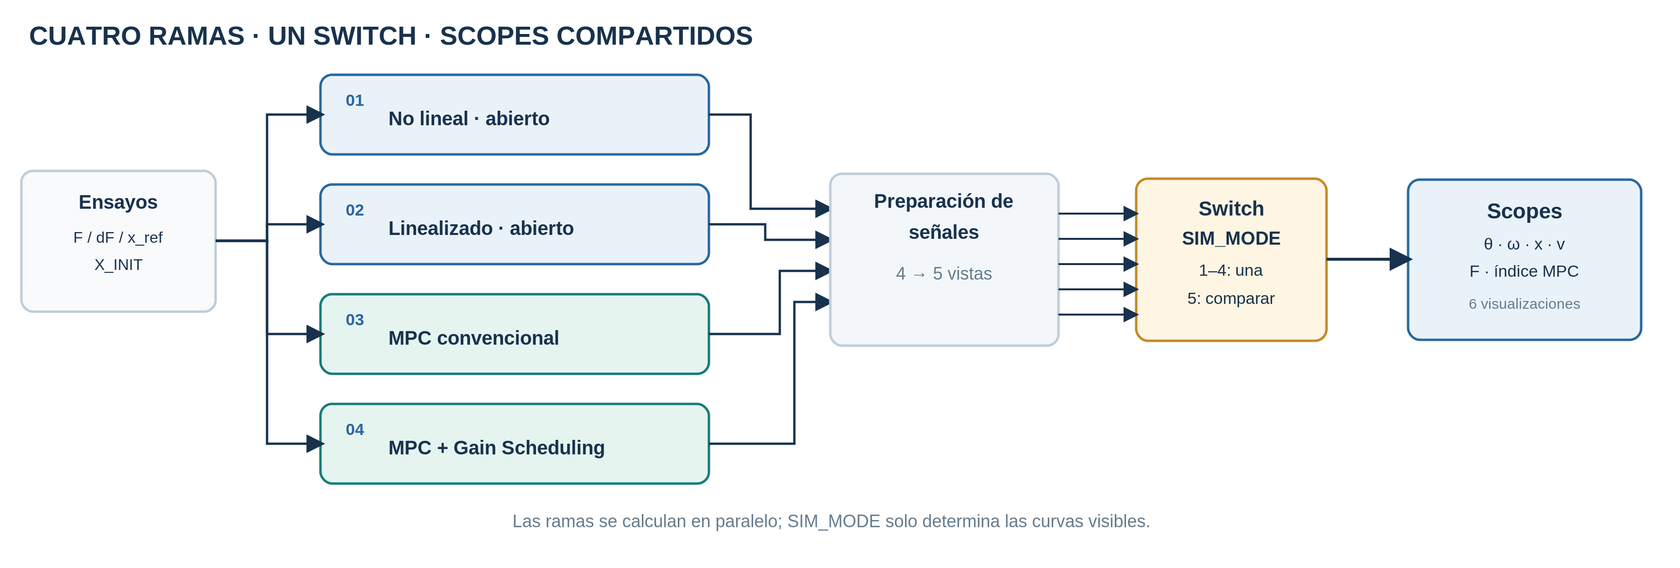

Figura 4. Diagrama del modelo único: cuatro ramas calculadas en paralelo, un switch de visualización y seis Scopes comunes. No se utiliza Variant Subsystem.

SIM_MODE = 1: no lineal en lazo abierto; 2: linealizado en la vertical, lazo abierto; 3: MPC convencional; 4: MPC con Gain Scheduling; 5: comparación de los cuatro. El modo 5 superpone las respuestas en los mismos Scopes.

Todas las ramas utilizan las mismas condiciones iniciales y perturbación. En los lazos abiertos se aplica una fuerza de ensayo; en los cerrados, cada MPC calcula F para seguir x_ref. Los Scopes muestran θ, θ̇, x, ẋ, F y el índice del MPC local. Un switch selecciona la visualización, no la ejecución de las plantas.

assert(isequal(size(A_LIN),[4 4]));
assert(isequal(size(B_LIN),[4 2]));
assert(isequal(size(C_LIN),[4 4]));
assert(isequal(size(D_LIN),[4 2]));
assert(norm(A_LIN-A0,'fro') < 1e-10);
assert(norm(B_LIN-B0(:,[2 1]),'fro') < 1e-10);
assert(numel(GSControllers)==3);
assert(all(isfinite(A_models(:))) && all(isfinite(B_models(:))));
assert(ismember(SIM_MODE,1:5));
assert(exist('mpc_nominal','var')==1 && isa(mpc_nominal,'mpc'),'Falta crear mpc_nominal. Ejecute Run All.');
assert(isa(mpc_gs_1,'mpc') && isa(mpc_gs_2,'mpc') && isa(mpc_gs_3,'mpc'));
disp('Planta lineal verificada; mpc_nominal y controladores locales creados.');

Planta lineal verificada; mpc_nominal y controladores locales creados.


## 9. Ejecución y criterios de evaluación

Ejecuta Run All en este Live Script para generar todos los parámetros, matrices y objetos mpc. Después ejecuta generate_simulink una sola vez, en la misma carpeta. El modelo mpc_pendulum_cart_simulink.slx recibe los datos desde el Workspace; al cambiar SIM_MODE entre 1 y 5 solo cambia la visualización, sin regenerar el archivo.

La evaluación debe comparar θ máximo, error de posición, tiempo de establecimiento, esfuerzo de control y conmutaciones del selector. El modelo lineal solo es una aproximación local válida cerca de la vertical. Para una comparación significativa se utilizan idénticas condiciones iniciales y perturbaciones; los lazos abiertos usan F de ensayo y los cerrados optimizan F.

fprintf('Inicializacion completa. Ejecute generate_simulink una sola vez.\n');

Inicializacion completa. Ejecute generate_simulink una sola vez.


fprintf('Cambie SIM_MODE = 1, 2, 3, 4 o 5 y ejecute sim(''mpc_pendulum_cart_simulink'').\n');

Cambie SIM_MODE = 1, 2, 3, 4 o 5 y ejecute sim('mpc_pendulum_cart_simulink').


Alcance de la simulación: el límite de fuerza es provisional, no se consideran límites de riel ni dinámica detallada del actuador y las linealizaciones de ±80° no son puntos estacionarios. Los resultados deberán validarse mediante la ejecución en MATLAB/Simulink R2026b.

## Fuentes

Guía del segundo parcial de Control Multivariable, Pontificia Universidad Javeriana. Modelo y parámetros del repositorio mpc_pendulum. Esquemas redibujados para esta implementación.

Derivación y simulación: https://www.mathworks.com/help/symbolic/derive-and-simulate-cart-pole-system.html

Control MPC: https://www.mathworks.com/help/mpc/ug/mpc-control-of-an-inverted-pendulum-on-a-cart.html

Gain Scheduling: https://la.mathworks.com/help/mpc/ug/gain-scheduled-mpc-control-of-an-inverted-pendulum-on-a-cart.html